# SAR

## Parameter

c = 3*10^8;                             % 송수신속도 [m/s]
pulsewidth = 10;                        % 펄스 폭 [ns]
h = 20000;                              % 탑재체 고도 [m]
gamma_m = 10;                           % 관측각도 [ °]

% < L-band > frequency : 1~2[GHz], wavelength : 15~30[cm]
% < X-band > frequency : 7.5~12[GHz], wavelength : 2.5~4[cm]
fc = 9;                                 % 운용주파수 [GHz]
lambda = c/(fc*10^9)                    % 파장 [m]

lambda = 0.0333


G = 6.67*10^-11;                        % 중력상수
M = 5.9722*10^24;                       % 지구의 질량 [kg]
Re = 6378000;                           % 지구반지름 [m]
v = sqrt(G*M/(h+Re))                    % 탑재체 속도 [m/s]

v = 7.8906e+03


L = 5;                                  % 안테나 길이 [m], 방위(azimuth)에 영향
W = 5;                                  % 안테나 폭 [m], 고도(elevation)에 영향
Ae = L*W*0.01;                          % 안테나 유효면적 [m^2]
eta = 70;                               % 안테나 효율 [%]

theta_az = 0.5*(lambda/L)*10^2;         % 안테나 빔 폭(azimuth) [ °]
theta_el = 0.5*(lambda/W)*10^2;         % 안테나 빔 폭(elevation) [ °]
A = 4*pi*Ae*(eta*10^-2)/lambda^2;       % 안테나 이득
A_dB = 10*log10(A)                      % 안테나 이득 [dB]  

A_dB = 32.9649


Bandwidth = (1/pulsewidth)*10^3;        % 대역폭 [MHz]
delta_az = L/2                          % 방위 분해능 [m]

delta_az = 2.5000

delta_r = c/(2*Bandwidth*10^6)          % 거리 분해능 [m]

delta_r = 1.5000

R = h/cos(deg2rad(gamma_m))             % 탑재체에서 관측지표까지의 거리[m]

R = 2.0309e+04


PRFmin = (2*v*sin(deg2rad(theta_az))... % 최소 PRF [Hz], PRFmax는 고려x
    *fc*10^9)/c

PRFmin = 2.7543e+03

PRImin = 1/PRFmin*10^6                  % 최소 PRI [μs], PRImax는 고려x

PRImin = 363.0673

## 설계

mode : strip-map & side a look 방식, resolution : 1m, drone height : 20km  

% 지표면에 비치는 빔의 길이
length_az = R/cos(deg2rad(theta_az));
length_el = R/cos(deg2rad(theta_el));
BeamWidth_xlength = 2*length_az*sin(deg2rad(theta_az))  % x축[m]

BeamWidth_xlength = 236.3032

BeamWidth_ylength = 2*length_el*sin(deg2rad(theta_el))  % y축[m]

BeamWidth_ylength = 236.3032

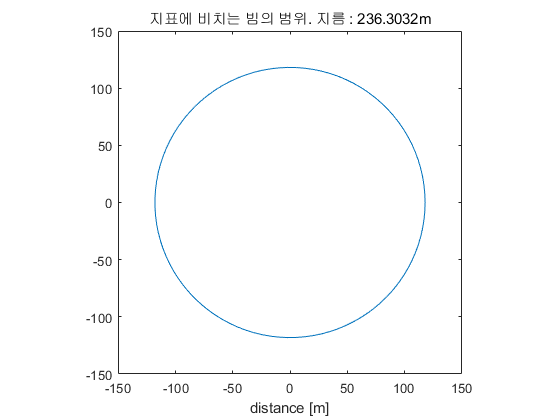


theta = linspace(0, 2*pi, 100);
x_circle = 1/2*BeamWidth_xlength*cos(theta);
y_circle = 1/2*BeamWidth_ylength*sin(theta);
plot(x_circle,y_circle);
title("지표에 비치는 빔의 범위. 지름 : "+BeamWidth_xlength +"m");
xlabel("distance [m]");
axis('square');

%-------------------------------------------------------------------------

% +z축에서 바라본 탑재체의 동선 및 송수신 신호
% 0.5[us]만큼의 시간을 기준, 총 50개의 신호를 송수신함.
v_test = v*10^-3                        % 탑재체 속도 [m/us]

v_test = 7.8906

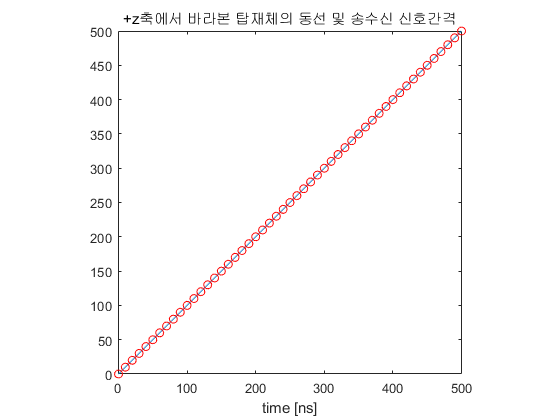

x = 0 : pulsewidth : 500;
y = 0 : pulsewidth : 500;
plot(x,y);
title("+z축에서 바라본 탑재체의 동선 및 송수신 신호간격");
xlabel("time [ns]");
axis('square');

hold on;
for i = 1:length(x)      
    x_trans = 0 : pulsewidth : 500;
    y_trans = 0 : pulsewidth : 500;
    % pause(0.5);
    drawnow;
    plot(x_trans(i),y_trans(i),"Marker",'o',"Color",'r')
end
hold off;

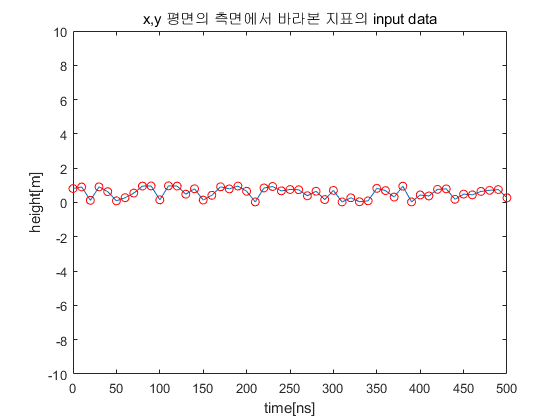

%-------------------------------------------------------------------------

% simulation1 : x,y 평면의 측면에서 바라본 지표의 input data
ground = rand(1,51);
ground_x = [ground];
plot(x,ground_x);
title("x,y 평면의 측면에서 바라본 지표의 input data");
xlabel("time[ns]");
ylabel("height[m]");
axis([0 500 -10 10])

hold on;
for i = 1:length(x)
    input_trans = 0 : pulsewidth : length(ground);
    % pause(0.5);
    drawnow;
    plot(x(i),ground_x(i),"Marker",'o',"Color",'r')
end
hold off;

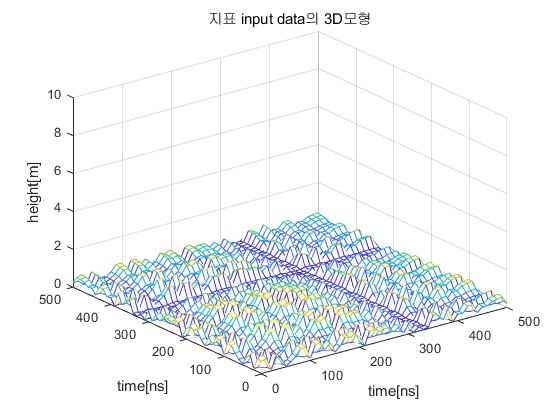


% 탑재체로부터 지표까지의 거리 value
ground_height = 20+ground_x;    
%------------------------------------------------------------------------

% simulation2 : 공간상에서 바라본 지표의 가상의 input data
ground_3d = [ground_x].*[ground_x]';
mesh(x,y,ground_3d);
title("지표 input data의 3D모형");
xlabel("time[ns]");
ylabel("time[ns]");
zlabel("height[m]");
axis([0 500 0 500 0 10]);


% *[ground_x].*[ground_x]'이외의 방법으로 data 만드는 방법은?

## Simulation 1

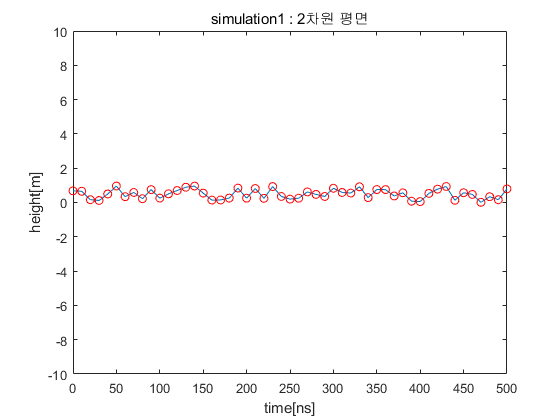

t = 0 : pulsewidth*10^-3 : pulsewidth;      % 0 : 0.01 : 10 [ns]
N_t = length(t);                            % N_t = 51
chirp_gain = 1;
chirp_fo = 1;
chirp_delta_tau = 0.5;
chirp_mu = 1;
%----------------------------------------------------------------

% simulation 1
ground = rand(1,51);
ground_x = [ground];
plot(x,ground_x);
title("simulation1 : 2차원 평면");
xlabel("time[ns]");
ylabel("height[m]");
axis([0 500 -10 10])

hold on;
for i = 1:length(x)
    input_trans = 0 : pulsewidth : length(ground);
    % pause(0.5);
    drawnow;
    plot(x(i),ground_x(i),"Marker",'o',"Color",'r')
end
hold off;

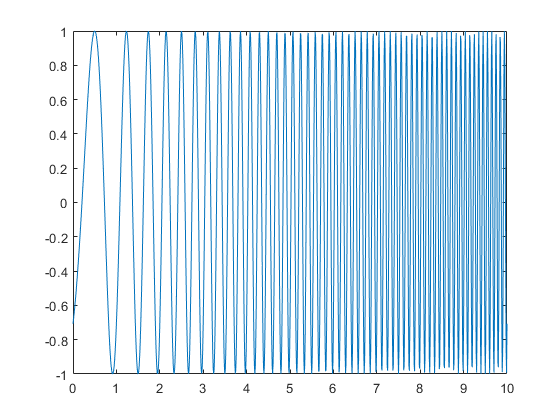


% chirp signal
st = chirp_gain.*cos(2*pi.*(chirp_fo*(t - chirp_delta_tau) + (chirp_mu/2).*(t - chirp_delta_tau).^2));
for i = 1:length(t) 
    rt = [st,zeros(1,N_t)];
    %rt = rt; % + randn(1,length(rt));          % noise      
end
plot(t,st);

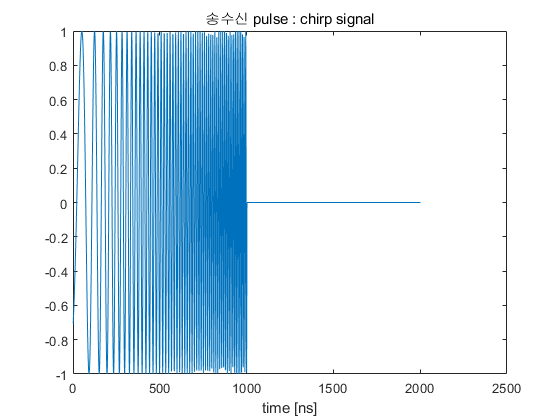

plot(rt);
title("송수신 pulse : chirp signal");
xlabel("time [ns]");

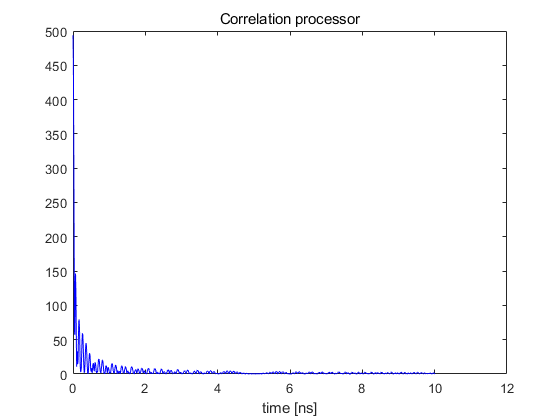


ct = length(rt)-N_t;
    for k = 0:ct
        c(k+1) = rt(k+1:k+N_t)*(st)';
    end    
plot((0:length(c)-1)*pulsewidth*10^-3, abs(c),'b');
title("Correlation processor");
xlabel("time [ns]");

% plot(t,Xct,'b')

## Simulation 2

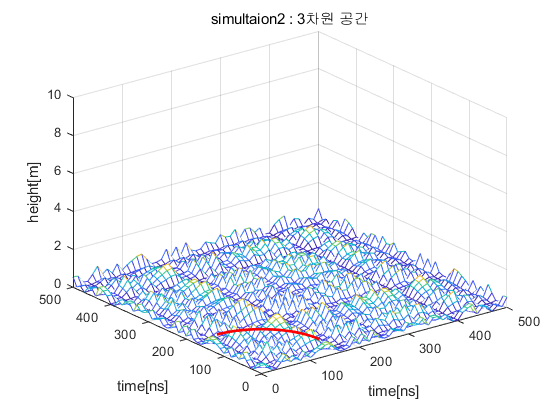

% simultaion 2
z_circle = ones(1,100);
ground_3d = [ground_x].*[ground_x]';
mesh(x,y,ground_3d);
title("simultaion2 : 3차원 공간");
xlabel("time[ns]");
ylabel("time[ns]");
zlabel("height[m]");
axis([0 500 0 500 0 10]);

hold on;
    plot3(x_circle,y_circle,z_circle,'r','LineWidth',2);
hold off;


% *3차원에서 resolution은 어떻게?